clc;
clear all;
warning off;
%     A1     b1      A2      b2      A5      b5      Tp      Tf     Tvl
%     Tv0    yita    S1      S2      S3      S4      k0      k1     k2      k3
lb = [
      0       %A1
      0       %b1
      0       %A2
      0       %b2
      0       %Tp
      0       %Tf0
      0       %Tvl
      0       %Tv0
      0.85    %yita
     ]; 

ub = [
      0.8     %A1
      0.8     %b1
      0.8     %A2
      0.8     %b2
      10       %Tp
      5       %Tf0
      15      %Tvl
      5      %Tv0
      0.95    %yita
     ];    

Npara = length(lb); 

A1   = 0.3         ; A2   = 0.3        ;
b1   = 0.3        ; b2   = 0.3           ;
Tp   = 5           ; Tf0  = 1             ;
Tvl  = 8            ; Tv0  = 2             ;
st   = 0.19          ; yita = 0.95          ;

para_init = [A1,b1,A2,b2,...
            Tp,Tf0,Tvl,Tv0,...
            yita];

%% ==================== 1. 工况设置 ============================
meanangle    = 9.6;
averageangle = 7;
conditions   = input_condition(meanangle,averageangle);
airfoildata  = input_afdata;

CFDdatapath = 're1e6_9.6_f0.6.txt';

%% ==================== 2. 整理变量 ============================
setcase.meanangle    = meanangle;
setcase.averageangle = averageangle;
setcase.conditions   = conditions;
setcase.airfoldata   = airfoildata;
setcase.CFDdatapath  = CFDdatapath;

para_local_DTW = run_optimal_DTW(para_init,Npara,lb,ub,setcase);

===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====

单目标优化:
9 变量
1 非线性不等式约束

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          12675       1.30784            0      0
    2          25094       1.30775            0      0
    3          37513       1.30767            0      0
优化结束: 适应度值的平均变化小于 options.FunctionTolerance 且约束违反值小于 options.ConstraintTolerance。
===== 优化完成！最优适应度值 = 1.30767361 =====

==================== 原始参数 ↔ 优化后最优参数 对比表 ====================
原始适应度=3.163510 | 优化适应度=1.307674
   A1 : 原始值=0.300000 | 优化值=0.604972
   b1 : 原始值=0.300000 | 优化值=0.473665
   A2 : 原始值=0.300000 | 优化值=0.593856
   b2 : 原始值=0.300000 | 优化值=0.506618
   Tp : 原始值=5.000000 | 优化值=1.638165
  Tf0 : 原始值=1.000000 | 优化值=3.119699
  Tvl : 原始值=8.000000 | 优化值=0.380018
  Tv0 : 原始值=2.00

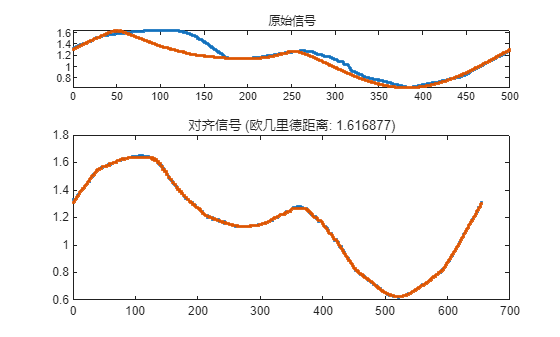

ans = 1.6169

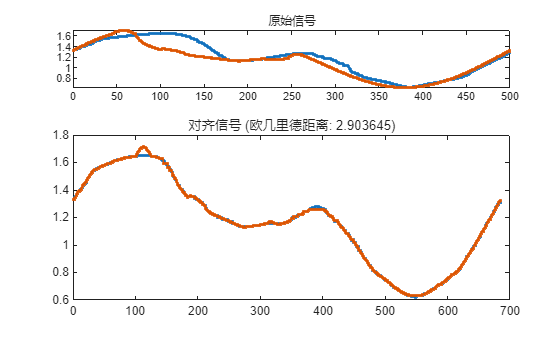

ans = 2.9036

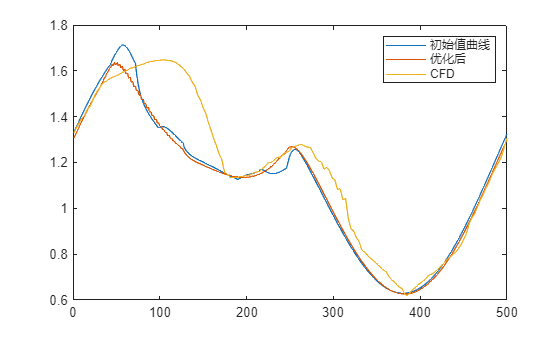

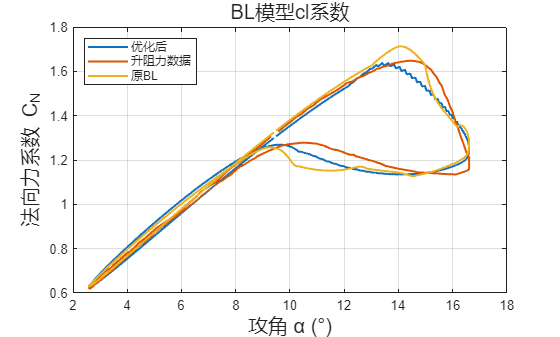

compare_optimal_result_DTW(para_local_DTW,para_init,setcase);

para_local_ARE = run_optimal_ARE(para_init,Npara,lb,ub,setcase);

===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====

单目标优化:
9 变量
1 非线性不等式约束

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          12675     0.0363111            0      0
    2          25094     0.0362024            0      0
    3          37513     0.0362002            0      0
优化结束: 适应度值的平均变化小于 options.FunctionTolerance 且约束违反值小于 options.ConstraintTolerance。
===== 优化完成！最优适应度值 = 0.03620021 =====

==================== 原始参数 ↔ 优化后最优参数 对比表 ====================
原始适应度=0.081873 | 优化适应度=0.036200
   A1 : 原始值=0.300000 | 优化值=0.382981
   b1 : 原始值=0.300000 | 优化值=0.088571
   A2 : 原始值=0.300000 | 优化值=0.676679
   b2 : 原始值=0.300000 | 优化值=0.646332
   Tp : 原始值=5.000000 | 优化值=6.567401
  Tf0 : 原始值=1.000000 | 优化值=0.007350
  Tvl : 原始值=8.000000 | 优化值=0.087706
  Tv0 : 原始值=2.00

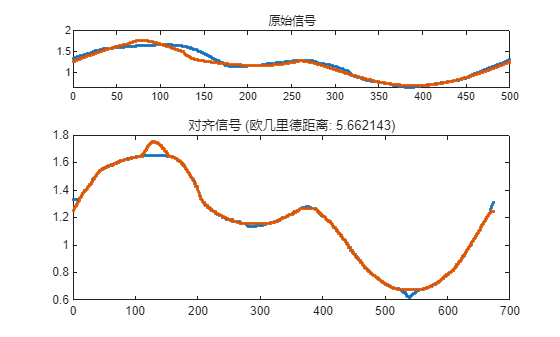

ans = 5.6621

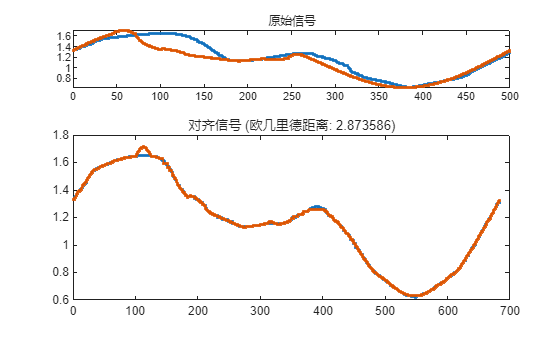

ans = 2.8736

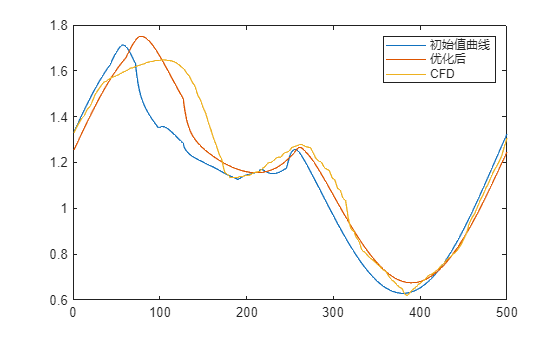

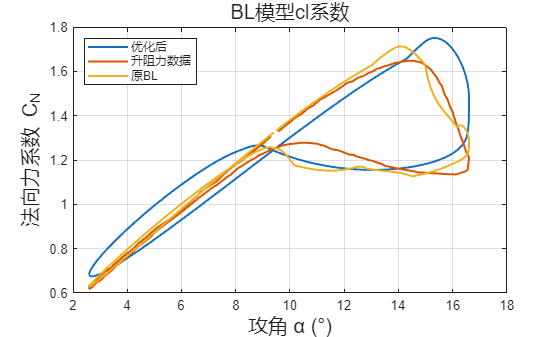

compare_optimal_result_ARE(para_local_ARE,para_init,setcase);

para_local_MSE = run_optimal_MSE(para_init,Npara,lb,ub,setcase);

===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====

单目标优化:
9 变量
1 非线性不等式约束

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          12675      0.386662            0      0
    2          25094      0.386141            0      0
    3          37513      0.386138            0      0
优化结束: 适应度值的平均变化小于 options.FunctionTolerance 且约束违反值小于 options.ConstraintTolerance。
===== 优化完成！最优适应度值 = 0.38613806 =====

==================== 原始参数 ↔ 优化后最优参数 对比表 ====================
原始适应度=1.776013 | 优化适应度=0.386138
   A1 : 原始值=0.300000 | 优化值=0.295491
   b1 : 原始值=0.300000 | 优化值=0.092873
   A2 : 原始值=0.300000 | 优化值=0.246533
   b2 : 原始值=0.300000 | 优化值=0.063292
   Tp : 原始值=5.000000 | 优化值=9.363728
  Tf0 : 原始值=1.000000 | 优化值=0.000712
  Tvl : 原始值=8.000000 | 优化值=0.345595
  Tv0 : 原始值=2.00

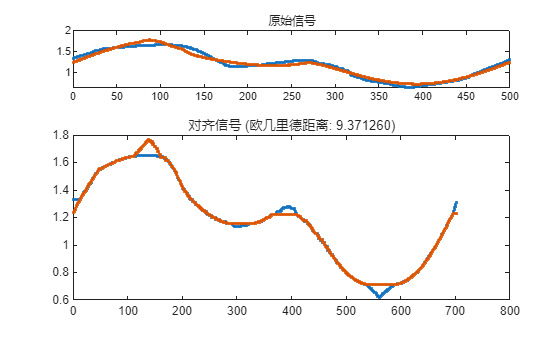

ans = 9.3713

ans = 2.9036

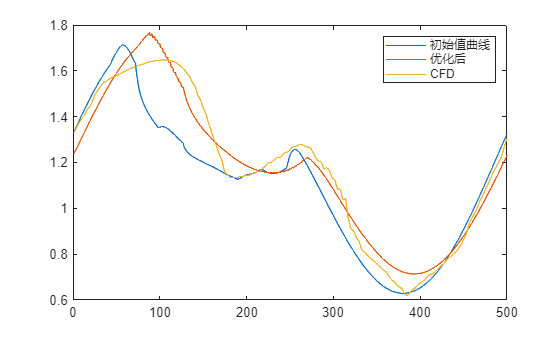

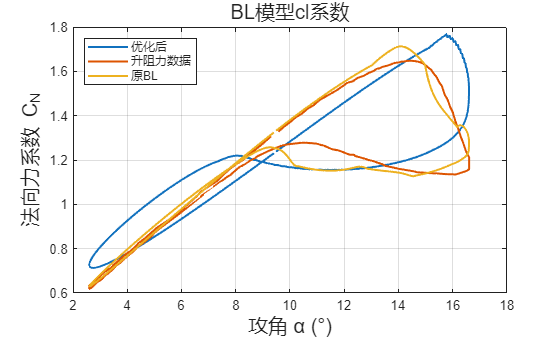

compare_optimal_result_MSE(para_local_MSE,para_init,setcase);

para_local_GZ = run_optimal_GZ(para_init,Npara,lb,ub,setcase);

===== 动态失速BL模型参数优化开始【CFD拟合+面积相似度】 =====

单目标优化:
9 变量
1 非线性不等式约束

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1          12675      0.470227            0      0
    2          25094      0.454097            0      0
    3          37513      0.414183            0      0
优化结束: 适应度值的平均变化小于 options.FunctionTolerance 且约束违反值小于 options.ConstraintTolerance。
===== 优化完成！最优适应度值 = 0.41418288 =====

==================== 原始参数 ↔ 优化后最优参数 对比表 ====================
原始适应度=0.081877 | 优化适应度=0.087078
   A1 : 原始值=0.300000 | 优化值=0.654258
   b1 : 原始值=0.300000 | 优化值=0.797140
   A2 : 原始值=0.300000 | 优化值=0.620510
   b2 : 原始值=0.300000 | 优化值=0.796308
   Tp : 原始值=5.000000 | 优化值=2.767311
  Tf0 : 原始值=1.000000 | 优化值=0.460140
  Tvl : 原始值=8.000000 | 优化值=14.998841
  Tv0 : 原始值=2.0

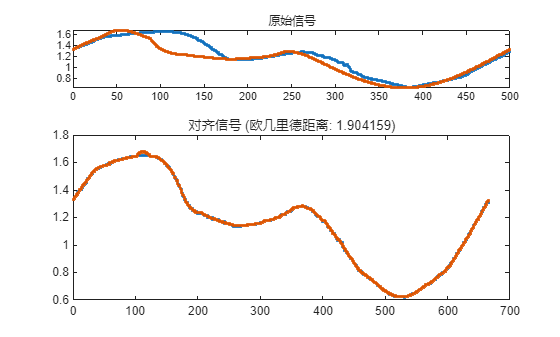

ans = 1.9042

ans = 2.9036

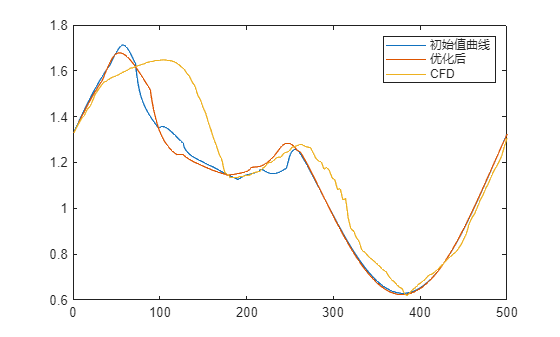

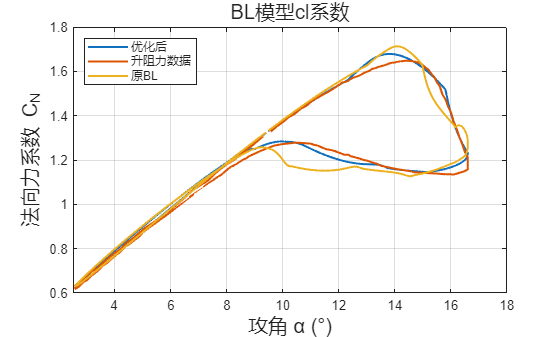

compare_optimal_result_GZ(para_local_GZ,para_init,setcase);

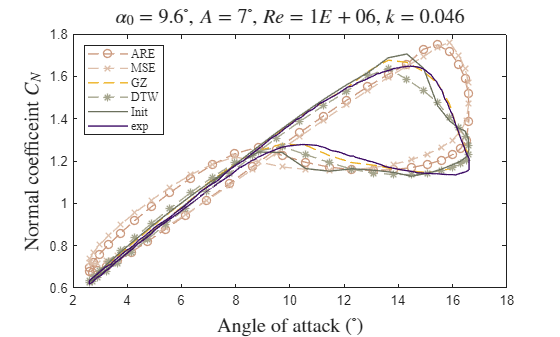

load("data_collection_ARE.mat")
ARE_data = [ARE_data(1:10:end,:)
            ARE_data(1,:)];
load("data_collection_DTW.mat");
DTW_data = [DTW_data(1:10:end,:)
            DTW_data(1,:)];
load("data_collection_GZ.mat");
GZ_data = [GZ_data(1:10:end,:)
            GZ_data(1,:)];
load("data_collection_MSE.mat");
MSE_data = [MSE_data(1:10:end,:)
            MSE_data(1,:)];

init_data = [init_data(1:10:end,:)
             init_data(1,:)];

exp_data = [exp_data
            exp_data(1,:)];

figure
fontsize = 15;
line = 1;
% plot(ARE_data(:,1) ,ARE_data(:,2) ,'o--','LineWidth',line,'Color',[237/255 179/255 39/255])
% hold on
% plot(DTW_data(:,1) ,DTW_data(:,2) ,'*--','LineWidth',line,'Color',[243/255 126/255 120/255])
% plot(MSE_data(:,1) ,MSE_data(:,2) ,'x--','LineWidth',line,'Color',[65/255  137/255 200/255])
% plot(init_data(:,1),init_data(:,2),      'LineWidth',line,'Color',[141/255 90/255  133/255])
% plot(exp_data(:,1) ,exp_data(:,2) ,      'LineWidth',line,'Color',[58/255  9/255   100/255])

plot(ARE_data(:,1) ,ARE_data(:,2) ,'o--','LineWidth',line,'Color',[203/255 153/255 126/255])
hold on
plot(MSE_data(:,1) ,MSE_data(:,2) ,'x--','LineWidth',line,'Color',[221/255 190/255 169/255])
plot(GZ_data(:,1) ,GZ_data(:,2) ,'--','LineWidth',line)
plot(DTW_data(:,1) ,DTW_data(:,2) ,'*--','LineWidth',line,'Color',[165/255 165/255 141/255])
plot(init_data(:,1),init_data(:,2),      'LineWidth',line,'Color',[107/255 112/255 92/255])
plot(exp_data(:,1) ,exp_data(:,2) ,      'LineWidth',line,'Color',[58/255  9/255   100/255])

legend('ARE','MSE','GZ','DTW',"Init",'exp','Location', 'northwest','FontName', 'Times New Roman');
title(sprintf('$\\alpha_0=%.1f^\\circ$, $A=%d^\\circ$, $Re=%.0E$, $k=%.3f$', meanangle, averageangle,conditions.Re,conditions.k), ...
       'Interpreter', 'latex', ...    
       'FontName', 'Times New Roman', ...  
       'FontSize', fontsize);

xlabel('Angle of attack ($^\circ$)', ... 
       'Interpreter', 'latex', ...    
       'FontName', 'Times New Roman', ...  
       'FontSize', fontsize); 

ylabel('Normal coefficeint $C_N$', ... 
       'Interpreter', 'latex', ...    
       'FontName', 'Times New Roman', ...  
       'FontSize', fontsize);
saveas(gcf, ['opt_compare','.png']);
exportgraphics(gcf,'opt_compare.pdf','ContentType', 'vector')